# Using simulink to visualise heating system behaviour

The control101 toolbox focuses mainly on linear models and thus simple MATLAB code is sufficient to illustrate the core behaviours. However, the real world is full of more complex components and connections. In such cases writing code can be messy or difficult and it is often easier to capture the scenario using tools such as simulink.

This livescript is a brief introduction to the use of simulink to model and simulate a simple heating systems. More importantly, it shows how integration with MATLAB code can make running the simulink file very efficient to allow systematic investigations for a range of parameter values and specifically in this case, the impact of the inclusion of non-linear components which are harder to handle in simple MATLAB code. This livescript file makes use of the following simulink file:

- Heating_system_control101.slx 

For more generic and comprehensive help on and introduction to Simulink, use the Mathworks onramp website.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

*****************************


Section 2 illustrations below


File written by J.A.Rossiter, University of Sheffield                         

## Preamble

Many simulink files have a large number of parameters which are most conveniently defined with a supporting MATLAB script and thus one might as well run the simulink file directly from the same script. This resource defines all the values in the simulink file explicitly and uses the simple options of a step input and a scope. This is the simplest example of using simulink to investigate system behaviours but is somewhat clumsy in that any parameter changes are hardwiredneed to be entered through the simulink options by opening the relevant blocks. Moreover, as this example has duplicated the system 3 times to allow for different scenarios, any system change would need to entered 3 times. Hopefully this will encourage readers to think about how such a scenario could be handled more efficiently as their skills increase.

For more generic and comprehensive help on and introduction to Simulink, use the Mathworks onramp website.

## 1. Simple heating system models

A heating system, in the linear case, has a simple model based on power/energy balance, that is:


$$C\frac{d\theta }{\textrm{dt}}=k\left(\theta -\theta_o \right)+W;$$


where $\theta$ is the room temperature, $\theta_o$ is the external temperature, *C* is the heat capacity, *k* determines heat loss and *W* is the power supplied. For this resource a simple model is chosen whereby:


$$\frac{C}{k}=1,\;k=0\ldotp 5$$


As the purpose of this resource is also to introduce some realistic components, we assume that the temperature measurement $\theta_m$ is not immediate and is subject to some delay. Consequently we assume that:

$\theta_m \left(t\right)=\theta \left(t-d\right)$  where *d *is the delay. Here the delay is 0.5

**Remark**: It is implicit throughout this resource that we are using deviation variables relative to some steady-state and thus 'negative power' is not really negative, but rather less than the expected steady-state.

### 1.1. Introducing feedback to govern the power/heat supply

In practice we want to choose the hearing in order to achieve a given temperature $\theta_r$=20 and thus a feedback loop can be introduced. The simplest feedback loop could be a proportional compensator, for example:


$$W=1\ldotp 5\left(\theta_r -\theta_m \right)$$


Unsurprisingly the performance is poor and has offset from the target of 20..

### 1.2 Adding dead zones and simple switching to the compensator

Some simple heating systems operate more on a logical basis and thus, changes from positive to negative control only occur when the error is substantial or indeed, if the error is small, the control is switched off. This avoids unnecessary chatter and wear and tear and is simple to code. Consequently one might have:

$\left|\theta_r -\theta_m \right|<0\ldotp 1\;\;\;\to \;\;W\left(t\right)=W\left(t-1\right)$;               that is continue with existing power.

$\left|\theta_r -\theta_m \right|>0\ldotp 1\;\;\;\to \;\;W=5\;\textrm{sign}\left(\theta_r -\theta_m \right)$          that is maximum or minimun power depending upon the error sign.

This is like a historical on-off option. 

### 1.3 PI compensation

Of course, most readers will know that for such low order systems, PI compensation is quite effective and thus one should also investigate this option. Hence:


$$W\left(t\right)=K_p \left(\theta_r -\theta_m \right)+K_i \int_0^t \left(\theta_r -\theta_m \right)\textrm{dt}$$



$$K_p =5*0\ldotp 27,\;K_i =5*0\ldotp 18$$


## 2. Simulink file and simulation

A file which considers all 3 scenarios simultaneously is available in ***Heating_System_control101.slx***. Open the file and open the scopes to see the results. Note that in the scopes:

- One line is the measured temperature which is delayed and in absolute values.

- The 2nd line is the undelayed temperature, but expressed in deviation form (relative to 15 degrees).

- It is easy to edit the simulink source to view other signals, such as the heating, as desired. 

Some core observations:

- The simple proportional feedback leads to closed-loop oscillation due to a combination of large proportional alongside a large delay. Readers could try reducing the proportional gain.

- The on-off control, as expected, causes a saw-tooth pattern and generally would be considered unacceptable.

- The PI compensator has lower gains than the proportional, but also an integral and thus achieves offset free tracking.

- The design of the file is clear and simple and handles the non-linear components easily, but is somewhat cumbersome to use iteratively in design and otherwise.

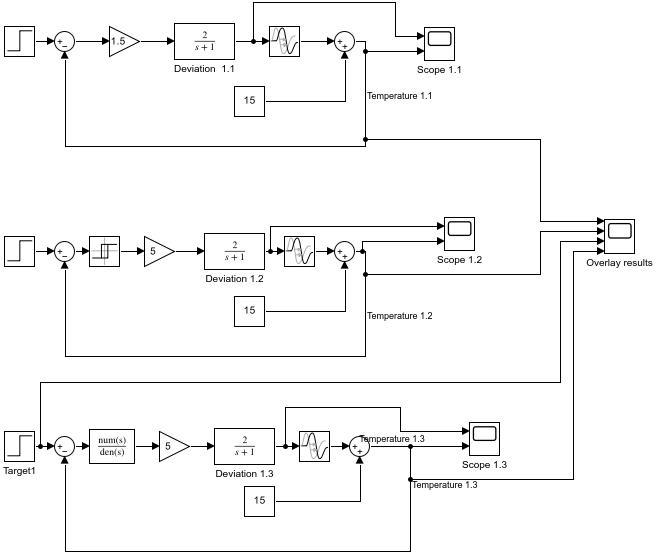

**Figure 1**: Screen capture of*** Heating_System_control101.slx.*** 

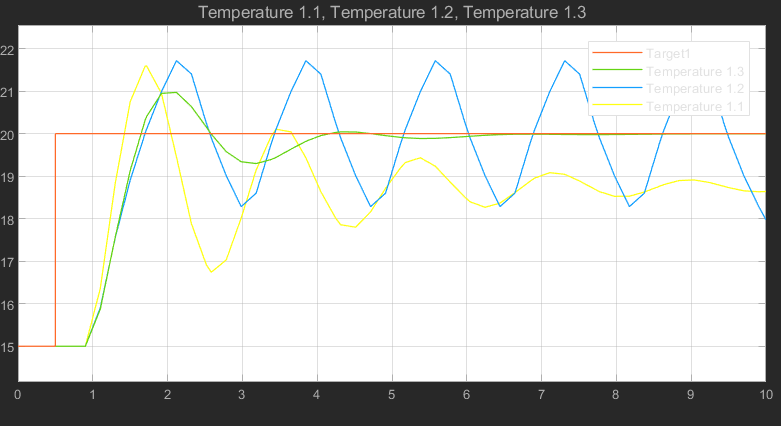

**Figure 1.2** Illustration of the output from the overlay scope

disp('*****************************')
disp('Section 2 illustrations below')

% to open simulink file and view the scopes
open Heating_System_control101.slx  

% Simulation - results will appear in the scopes
sim("Heating_System_control101.slx");

%print(['-sHeating_System_control101'],'-djpeg',['Heating_System_control101.jpg'])